%(a)
rng(13);
%(b)
students = 5000

students = 5000

questions = 40

questions = 40

%(b)
p_i = 0.35 + (0.95 - 0.35) * rand(1, questions)

p_i =     0.8166    0.4925    0.8446    0.9294    0.9336    0.6221    0.7154    0.8153    0.7350    0.7832    0.3710    0.5291    0.3851    0.8642    0.5737    0.7579    0.5038    0.5585    0.3556    0.5650    0.9195    0.4807    0.5416    0.9007    0.3691    0.3891    0.7279    0.8743    0.3552    0.7979    0.8377    0.3954    0.7439    0.6556    0.6379    0.9233    0.3500    0.4982    0.7773    0.5447


%(c)
exam_results = rand(students, questions) < p_i

exam_results = 5000×40 logical 배열
   1   1   1   1   1   0   0   1   1   0   0   0   1   0   1   1   0   1   0   1   1   0   1   1   0   0   1   1   0   1   1   1   1   1   1   1   0   1   1   0
   1   0   1   1   1   1   1   1   1   1   0   0   0   1   1   1   0   1   1   0   1   1   1   1   1   0   1   1   1   0   1   1   0   0   0   1   0   0   1   1
   0   0   0   1   0   0   1   1   0   1   0   1   1   1   1   1   0   1   0   0   1   0   1   1   1   0   1   1   0   1   1   0   1   1   1   1   1   1   1   1
   1   0   1   1   1   1   1   1   1   1   1   1   0   1   0   1   1   1   1   1   1   0   1   1   1   0   1   1   0   0   1   1   0   1   0   1   1   0   1   1
   1   1   1   1   1   1   1   1   0   0   0   1   0   1   0   1   1   0   1   1   1   1   0   1   1   0   0   1   0   1   1   0   1   1   1   1   1   0   1   0
   1   1   0   1   1   0   1   1   1   0   0   0   0   1   1   1   1   0   0   0   1   0   0   1   1   1   1   1   0   0   0   0   1   1   1   0   0   0   1   1


%(d)
total_scores = sum(exam_results, 2)     

total_scores =     26
    27
    26
    30
    27
    22
    26
    26
    22
    27


mean_scores = mean(exam_results, 2)    

mean_scores =     0.6500
    0.6750
    0.6500
    0.7500
    0.6750
    0.5500
    0.6500
    0.6500
    0.5500
    0.6750


std_scores = std(double(exam_results), 0, 2)

std_scores =     0.4830
    0.4743
    0.4830
    0.4385
    0.4743
    0.5038
    0.4830
    0.4830
    0.5038
    0.4743


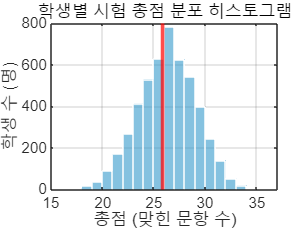

%(e)
overall_mean = mean(total_scores);

figure;
histogram(total_scores, 'BinWidth', 1, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'w');
hold on;
xline(overall_mean, 'r', 'LineWidth', 2);
title('학생별 시험 총점 분포 히스토그램');
xlabel('총점 (맞힌 문항 수)');
ylabel('학생 수 (명)');
grid on;


ratio_above_mean = sum(total_scores >= overall_mean) / students

ratio_above_mean = 0.5640

num_boxes = 10000;     
items_per_box = 20;     
true_mean = 100;        
true_std = 4;
%(a)
product_weights = true_mean + true_std * randn(num_boxes, items_per_box)

product_weights =   101.0434  101.6909  101.7657  101.3431  100.9140   96.6957   99.8744   99.9888  100.3273  100.6569   97.1317  103.3401   96.7060  100.6657  105.3996   98.9761   99.0120   96.2994   99.1301  105.1663
   99.1162  101.6301  100.1975   94.8472  105.7718  100.7689   98.0498  101.9609  102.5781   97.3430   99.9714   95.9500   99.8770  111.3160   99.7836   93.9461   95.6746   97.4301  100.6284   99.4196
  107.2986  107.4517  102.6226   98.4568   97.2050   98.7857  102.9546   97.9720   97.9725  104.8565  101.0484  102.5710   98.1853  101.0795   98.0160  107.2927  101.7288  101.3423   98.7192  104.7754
   99.8576  104.9055   97.9948  103.8309   97.1699   99.3841  103.9518   97.0496   95.8036  103.4582  105.7587  110.5577   99.3898   96.6842  100.1130  101.2428   95.2758   92.0451  102.5542   94.5768
  100.5394  107.5362  101.1599  100.0014   98.5455  103.4809  101.7066   99.7590   97.2744   97.5217   98.7425  103.2844   97.6122  101.9172  100.2182   92.8390  100.0172   98.68

%(b)
box_means = mean(product_weights, 2)

box_means =   100.3064
   99.8130
  101.5167
  100.0802
   99.8969
  100.3031
  100.1512
  100.8414
  100.2845
  100.1086


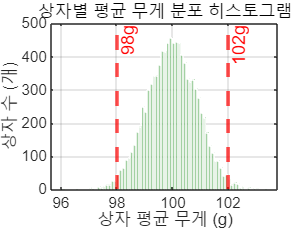

%(c)
fail_condition = (box_means < 98) | (box_means > 102);
%(d)
ail_rate = sum(fail_condition) / num_boxes;
%(e)
figure;
histogram(box_means, 'FaceColor', [0.4 0.7 0.4], 'EdgeColor', 'w');
hold on;

xline(98, '--r', 'LineWidth', 2, 'Label', '98g');
xline(102, '--r', 'LineWidth', 2, 'Label', '102g');

title('상자별 평균 무게 분포 히스토그램');
xlabel('상자 평균 무게 (g)');
ylabel('상자 수 (개)');
grid on;

num_simulations = 100000; 
A = 1.8;                   
threshold = 1.2;
%(a)
N = randn(num_simulations, 1);
%(b)
S = A + N

S =     1.8115
    0.9857
    1.3719
    0.5807
    0.8503
    3.1191
    1.2090
    0.9187
   -0.2777
   -0.1614


%(c)
detection_event = (S >= threshold);
%(d)
success_rate = sum(detection_event) / num_simulations

success_rate = 0.7250

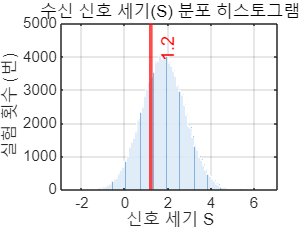

%(e)
figure;
histogram(S, 'FaceColor', [0.2 0.5 0.8], 'EdgeColor', 'w');
hold on;

xline(threshold, '-r', 'LineWidth', 2, 'Label', sprintf('%.1f', threshold));

title('수신 신호 세기(S) 분포 히스토그램');
xlabel('신호 세기 S');
ylabel('실험 횟수 (번)');
grid on;

num_days = 365;          
lambda_poisson = 180;     
mean_time = 6;            
std_time = 2;
%(a)
daily_orders = poissrnd(lambda_poisson, num_days, 1);
%(b)
daily_total_times = zeros(num_days, 1);

for day = 1:num_days
    orders_today = daily_orders(day); 
    
    if orders_today > 0
        
        order_times = mean_time + std_time * randn(orders_today, 1);
        
        order_times(order_times < 0) = 0;
        
        daily_total_times(day) = sum(order_times);
    else
        daily_total_times(day) = 0;
    end
end
%(c)
over_1200_condition = (daily_total_times > 1200);
ratio_over_1200 = sum(over_1200_condition) / num_days

ratio_over_1200 = 0.0712

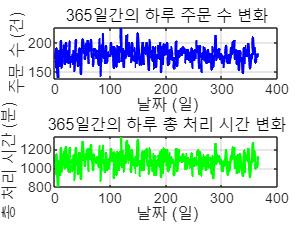

%(d)
figure;
subplot(2, 1, 1); % 2행 1열 그래프 중 첫 번째
plot(1:num_days, daily_orders, 'b-', 'LineWidth', 1.5);
title('365일간의 하루 주문 수 변화');
xlabel('날짜 (일)'); ylabel('주문 수 (건)');
grid on;

subplot(2, 1, 2); % 2행 1열 그래프 중 두 번째
plot(1:num_days, daily_total_times, 'g-', 'LineWidth', 1.5);
title('365일간의 하루 총 처리 시간 변화');
xlabel('날짜 (일)'); ylabel('총 처리 시간 (분)');
grid on;

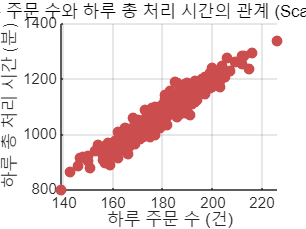

%(e)
figure;
scatter(daily_orders, daily_total_times, 'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);
title('하루 주문 수와 하루 총 처리 시간의 관계 (Scatter Plot)');
xlabel('하루 주문 수 (건)');
ylabel('하루 총 처리 시간 (분)');
grid on;

clear; clc;

num_simulations = 10000;  
num_sensors = 30;          
true_temp = 25;            
error_std = 0.8;
%(a)
sensor_measurements = true_temp + error_std * randn(num_simulations, num_sensors);
%(b)
avg_temperatures = mean(sensor_measurements, 2)

avg_temperatures =    24.8659
   25.1622
   24.9708
   25.0670
   25.1667
   25.1165
   25.1471
   24.9968
   24.8089
   24.9818


%(c)
within_range_event = (avg_temperatures >= 24.7) & (avg_temperatures <= 25.3);
%(d)
probability_within_range = sum(within_range_event) / num_simulations

probability_within_range = 0.9606

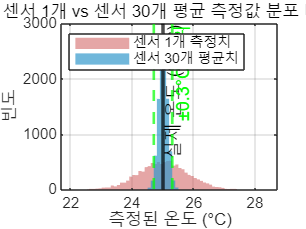

%(e)
single_sensor = sensor_measurements(:, 1);

figure;

histogram(single_sensor, 'BinWidth', 0.1, 'FaceColor', [0.8 0.3 0.3], 'FaceAlpha', 0.5, 'EdgeColor', 'none');
hold on;

histogram(avg_temperatures, 'BinWidth', 0.1, 'FaceColor', [0.2 0.6 0.8], 'FaceAlpha', 0.7, 'EdgeColor', 'none');

xline(true_temp, '-k', 'LineWidth', 2, 'Label', '실제 온도 (25°C)');

xline(24.7, '--g', 'LineWidth', 1.5);
xline(25.3, '--g', 'LineWidth', 1.5, 'Label', '±0.3°C 범위');

title('센서 1개 vs 센서 30개 평균 측정값 분포 비교');
xlabel('측정된 온도 (°C)');
ylabel('빈도');
legend('센서 1개 측정치', '센서 30개 평균치', 'Location', 'NorthWest');
grid on;

clear; clc;

num_paths = 5000;       
num_days = 60;          
initial_asset = 100;    
mean_return = 0.0008;   
std_return = 0.015;     
%(a)
daily_returns = mean_return + std_return * randn(num_paths, num_days);
%(b)
asset_paths = initial_asset * cumprod(1 + daily_returns, 2);
asset_paths = [ones(num_paths, 1) * initial_asset, asset_paths];
%(c)
final_assets = asset_paths(:, end);
mean_final = mean(final_assets)

mean_final = 104.9107

min_final = min(final_assets)

min_final = 69.8856

max_final = max(final_assets)

max_final = 161.3812

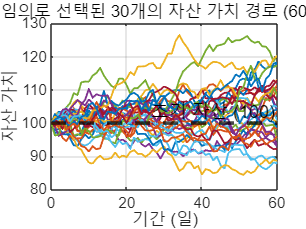

%(d)
prob_loss = sum(final_assets < 100) / num_paths;
%(e) 
rng(42);
selected_indices = randperm(num_paths, 30);

figure;
plot(0:num_days, asset_paths(selected_indices, :)', 'LineWidth', 1);
hold on;

yline(initial_asset, '--k', 'LineWidth', 2, 'Label', '초기 자산 (100)');

title('임의로 선택된 30개의 자산 가치 경로 (60일)');
xlabel('기간 (일)');
ylabel('자산 가치');
grid on;

clear; clc;

num_patients = 300;
mean_interarrival = 8;
mean_service = 10;
std_service = 3;

%(a)
interarrival_times = exprnd(mean_interarrival, num_patients, 1);
arrival_times = cumsum(interarrival_times)

arrival_times = 1.0e+03 *

    0.0040
    0.0181
    0.0400
    0.0404
    0.0407
    0.0424
    0.0519
    0.0705
    0.0736
    0.0801


%(b)
service_times = mean_service + std_service * randn(num_patients, 1);
service_times(service_times < 0) = 1;
%(c)
start_times = zeros(num_patients, 1);
end_times = zeros(num_patients, 1);

start_times(1) = arrival_times(1);
end_times(1) = start_times(1) + service_times(1);

for i = 2:num_patients
    start_times(i) = max(arrival_times(i), end_times(i-1));
    end_times(i) = start_times(i) + service_times(i);
end
%(d)
wait_times = start_times - arrival_times

wait_times =          0
         0
         0
    5.8906
   13.9122
   20.1701
   17.3229
   15.4275
   23.5467
   26.9183


%(e)
mean_wait = mean(wait_times);
max_wait = max(wait_times);
ratio_over_20 = sum(wait_times > 20) / num_patients;

fprintf('대기시간이 20분을 초과하는 환자 비율: %.2f%%\n', ratio_over_20 * 100);

대기시간이 20분을 초과하는 환자 비율: 95.33%


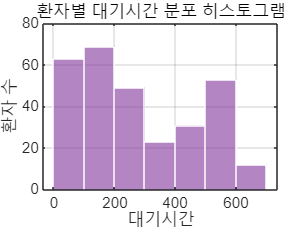


figure;
histogram(wait_times, 'FaceColor', [0.5 0.2 0.6], 'EdgeColor', 'w');
title('환자별 대기시간 분포 히스토그램');
xlabel('대기시간');
ylabel('환자 수');
grid on;

num_simulations = 100000;
p = [0.72, 0.81, 0.67, 0.90, 0.76];

%(a)
random_matrix = rand(num_simulations, 5);
%(b)
detection_matrix = random_matrix < p;
%(c)
detected_modules = sum(detection_matrix, 2)

detected_modules =      4
     5
     3
     5
     5
     4
     3
     5
     4
     2


%(d)
system_success = (detected_modules >= 3);
system_success_rate = sum(system_success) / num_simulations

system_success_rate = 0.9234

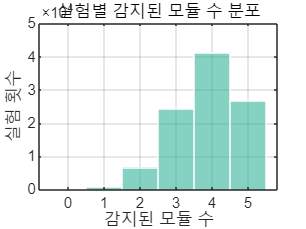

%(e)
figure;
histogram(detected_modules, 'BinEdges', -0.5:1:5.5, 'FaceColor', [0.2 0.7 0.6], 'EdgeColor', 'w');
title('실험별 감지된 모듈 수 분포');
xlabel('감지된 모듈 수');
ylabel('실험 횟수');
xticks(0:5);
grid on;

num_products = 50000;
p1 = 0.94;
p2 = 0.91;
p3 = 0.88;

%(a)
passed_stage1 = rand(num_products, 1) < p1;
%(b)
passed_stage2 = false(num_products, 1);
passed_stage2(passed_stage1) = rand(sum(passed_stage1), 1) < p2;
%(c)
passed_stage3 = false(num_products, 1);
passed_stage3(passed_stage2) = rand(sum(passed_stage2), 1) < p3;
%(d)
final_success_rate = sum(passed_stage3) / num_products

final_success_rate = 0.7519

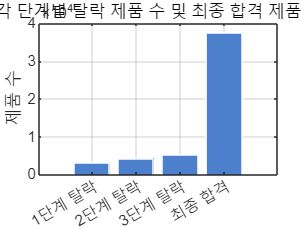

%(e)
failed_stage1 = sum(~passed_stage1);
failed_stage2 = sum(passed_stage1 & ~passed_stage2);
failed_stage3 = sum(passed_stage2 & ~passed_stage3);
final_passed = sum(passed_stage3);

counts = [failed_stage1, failed_stage2, failed_stage3, final_passed];
labels = {'1단계 탈락', '2단계 탈락', '3단계 탈락', '최종 합격'};

figure;
bar(counts, 'FaceColor', [0.3 0.5 0.8], 'EdgeColor', 'w');
set(gca, 'XTickLabel', labels);
title('각 단계별 탈락 제품 수 및 최종 합격 제품 수');
ylabel('제품 수');
grid on;

clear; clc;

num_days = 10000;
base_usage = 500;
server_std = 35;
additional_cooling = 120;
p_overload = 0.12;

%(a)
server_fluctuation = server_std * randn(num_days, 1);
%(b)
cooling_overload = rand(num_days, 1) < p_overload;
%(c)
total_power_usage = base_usage + server_fluctuation + (cooling_overload * additional_cooling);
%(d)
ratio_over_650 = sum(total_power_usage > 650) / num_days

ratio_over_650 = 0.0239

%(e)
mean_overload = mean(total_power_usage(cooling_overload));
mean_normal = mean(total_power_usage(~cooling_overload));

fprintf('과부하 발생일의 평균 전력 사용량: %.2f\n', mean_overload);

과부하 발생일의 평균 전력 사용량: 619.80


fprintf('과부하 비발생일의 평균 전력 사용량: %.2f\n', mean_normal);

과부하 비발생일의 평균 전력 사용량: 500.49


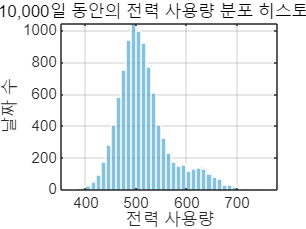


figure;
histogram(total_power_usage, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'w');
title('10,000일 동안의 전력 사용량 분포 히스토그램');
xlabel('전력 사용량');
ylabel('날짜 수');
grid on;